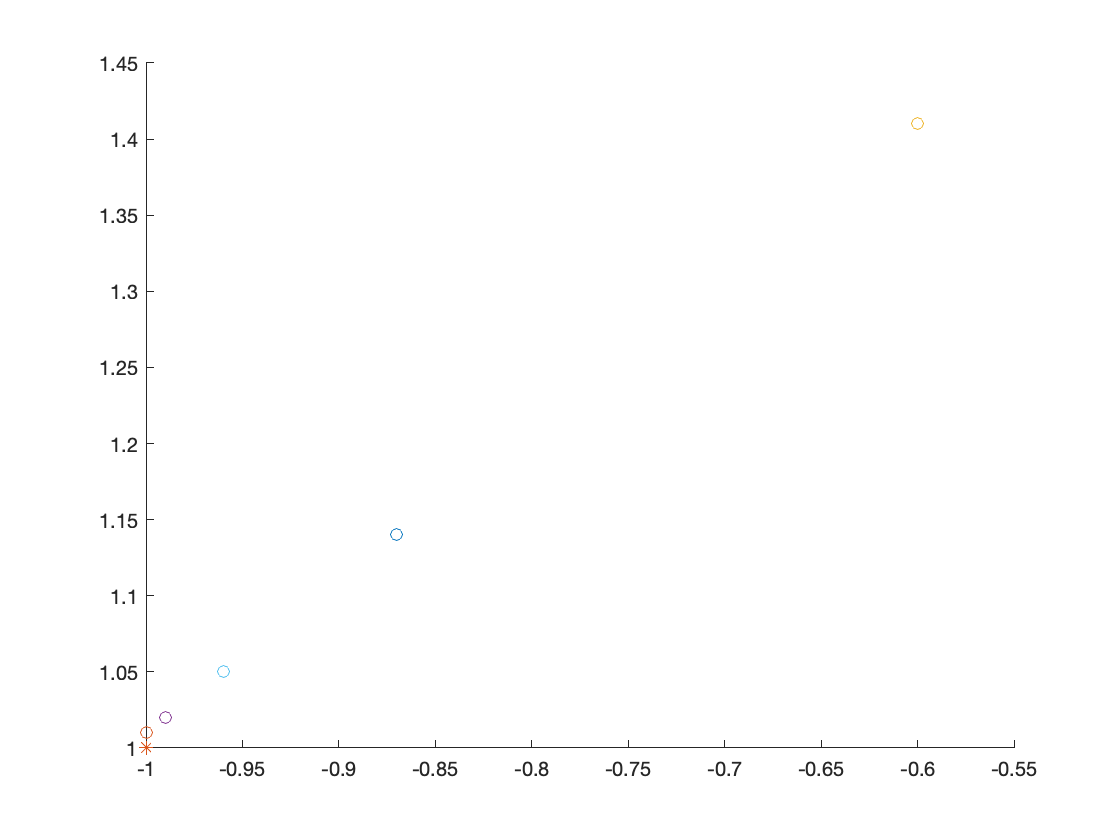

oooooo% Exercise 17.7
% I would like to hereby formally recognize my protent against this naming
% scheme.

n = [-1; 1];
z = [-1; 1.01];

S = [2 1; 1 2];

clf; hold on;
plotvec(n, '*');
plotvec(z, 'o');

curN = n;
curZ = z;
for i=1:4
    curN = S * curN;
    curZ = S * curZ;
    plotvec(curN, '*');
    plotvec(curZ, 'o');
end

% Excercise 17.8
[V, D] = eig([18 -2; 12 7])

V =     0.5547    0.2425
    0.8321    0.9701


D =     15     0
     0    10


[V, D] = eig([4 2; 1 3])

V =     0.8944   -0.7071
    0.4472    0.7071


D =      5     0
     0     2


[V, D] = eig([1 2; 3 2])

V =    -0.7071   -0.5547
    0.7071   -0.8321


D =     -1     0
     0     4


load('temps_bos_sp_dc.mat');

% Excercise 17.9
clf; hold on; grid;
dat = [centermean(b), centermean(w), centermean(s)] .* (1 / sqrt(length(b) - 1))

dat =    -0.1515   -0.2037    0.0379
   -0.1663   -0.2128    0.0574
   -0.2520   -0.3327    0.0482
   -0.2417   -0.2905    0.0482
   -0.3559   -0.4286    0.0779
   -0.2862   -0.3590    0.1133
   -0.0898   -0.2516    0.1224
   -0.2189   -0.2425    0.0711
   -0.2428   -0.2573    0.0802
   -0.3068   -0.2665    0.1122


covariance = dat' * dat

covariance =   284.8910  269.3927  -56.9729
  269.3927  284.1612  -57.2850
  -56.9729  -57.2850   39.4645


[V, D] = eig(covariance)

V =     0.7041    0.1233   -0.6994
   -0.7098    0.0910   -0.6985
   -0.0225    0.9882    0.1516


D =    15.1269         0         0
         0   27.0811         0
         0         0  566.3086


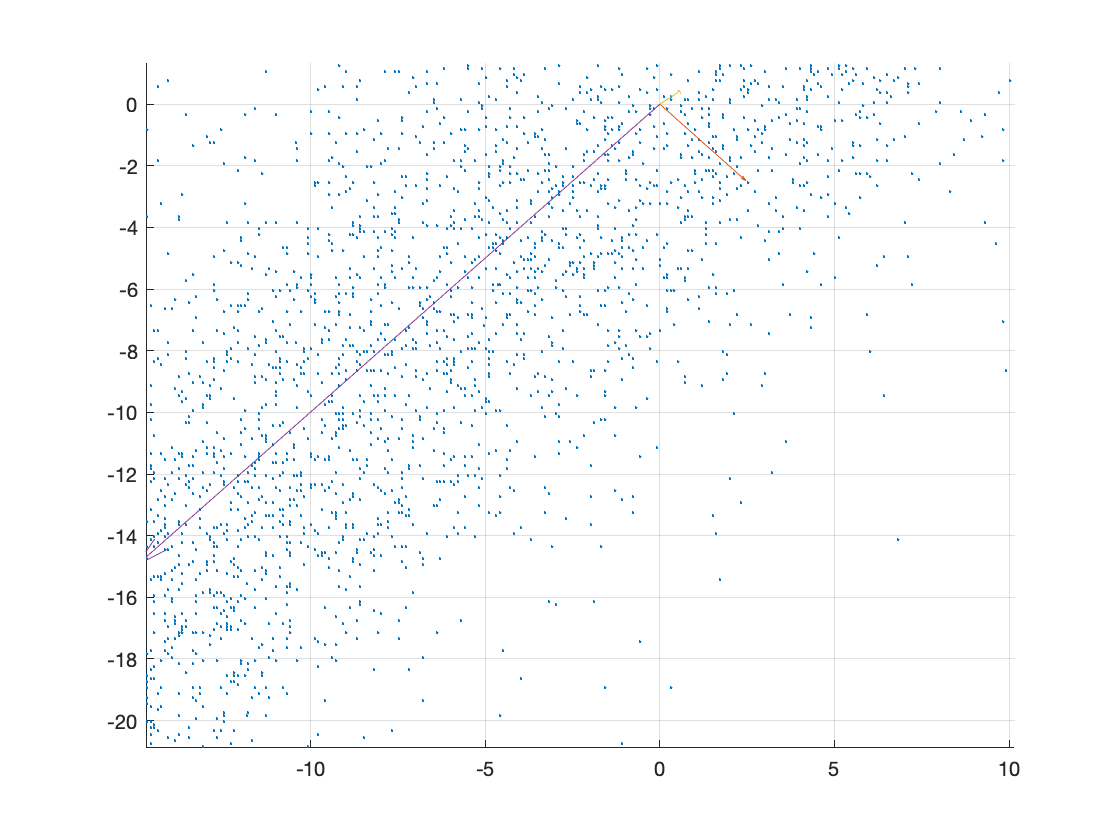

plot3(centermean(b), centermean(w), centermean(s), '*', 'MarkerSize', 0.1)
plotquiver3(V(:, 1) * sqrt(D(1, 1)))
plotquiver3(V(:, 2) * sqrt(D(2, 2)))
plotquiver3(V(:, 3) * sqrt(D(3, 3)))

function plotquiver3(v)
    quiver3(0, 0, 0, v(1), v(2), v(3))
end

function res = centermean(d)
    res = d - mean(d);
end
function plotvec(v, s)
    plot(v(1), v(2), s)
end